Half wave reactifier is a primitive convereter which employs single diode to only allow postive part of input wave 

## TIME  QUANTA

format long 
dt = 0.001;
tbeg = 0;
tend = 1;
t = tbeg:dt:tend;

## INPUT WAVE PARAMETERS

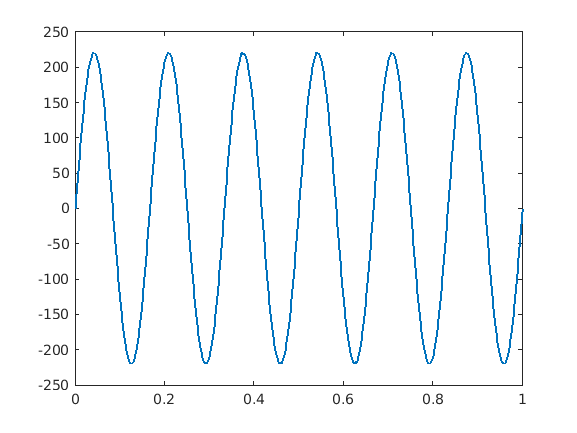

Vm = 220;
f = 6;
omega = 2*pi*f;
Vin = 220*sin(omega*t);
plot(t,Vin,"LineWidth",2)

## OUTPUT VOLTAGE WAVE

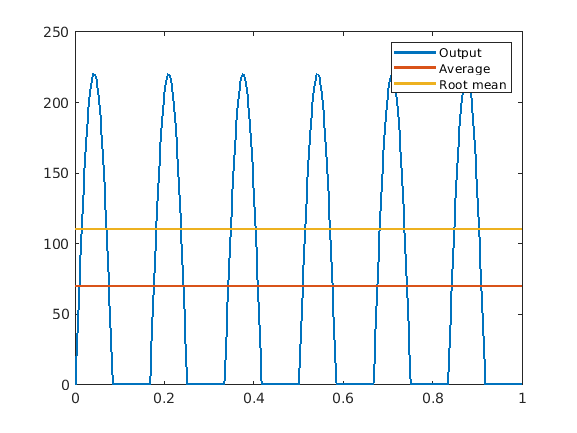

Vabs = abs(Vin);
Vo = (Vin + Vabs)/2;
plot(t,Vo,"LineWidth",2)
hold on
plot(t,Vavg_h,"LineWidth",2)
plot(t,Vrms_h,"LineWidth",2)
hold off
legend('Output','Average','Root mean')

## Average Voltage

Vavg = sum(Vo*dt)

Vavg =   70.027253424163519


Vavg_h = ones(size(t))*Vavg;

Vavg_h =   70.027253424163519  70.027253424163519  70.027253424163519  70.027253424163519  70.027253424163519  70.027253424163519  70.027253424163519  70.027253424163519  70.027253424163519  70.027253424163519  70.027253424163519  70.027253424163519  70.027253424163519  70.027253424163519  70.027253424163519  70.027253424163519  70.027253424163519  70.027253424163519  70.027253424163519  70.027253424163519  70.027253424163519  70.027253424163519  70.027253424163519  70.027253424163519  70.027253424163519  70.027253424163519  70.027253424163519  70.027253424163519  70.027253424163519  70.027253424163519  70.027253424163519  70.027253424163519  70.027253424163519  70.027253424163519  70.027253424163519  70.027253424163519  70.027253424163519  70.027253424163519  70.027253424163519  70.027253424163519  70.027253424163519  70.027253424163519  70.027253424163519  70.027253424163519  70.027253424163519  70.027253424163519  70.027253424163519  70.027253424163519  70.027253424163519  70.027253

## RMS VOLTAGE

Vrms = (sum(Vo .* Vo *dt))^0.5

Vrms =      1.100000000000000e+02


Vrms_h = ones(size(t))*Vrms;

FF = Vrms/Vavg

FF =    1.570816997972443


RF = ((FF^2) -1)^0.5

RF =    1.211390127547339


EFFi =    0.405274067944795
